**ENGN1930B Homework 2**

**Instructor: Dr. Jonghwan Lee**

**Name: Kuan-Min Lee**

**Problem 1.4**

For this problem set, the sinusoidal function:

**f(x) = sin(x) + 0.5*w(x) for x = (0,10*pi)**

**w(x): white noise with variance of 1.0**

is generated and convoluted with a normalized, rectangular kernel with width of pi/2.

To start with this, we first generate the f(x) function:

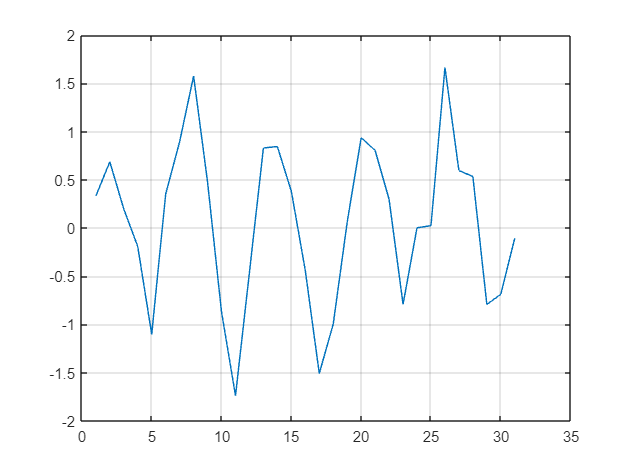

clear

x=1:10*pi; % get sample x [1, 10*pi]
w = randn(size(x)); % setup white noise function
f=sin(x)+0.5*w; % setup sinusoidal function

figure;
plot(x,f);
xlim([0 35]);
grid on

Later, we generate the convolutional kernel with width of pi/2:

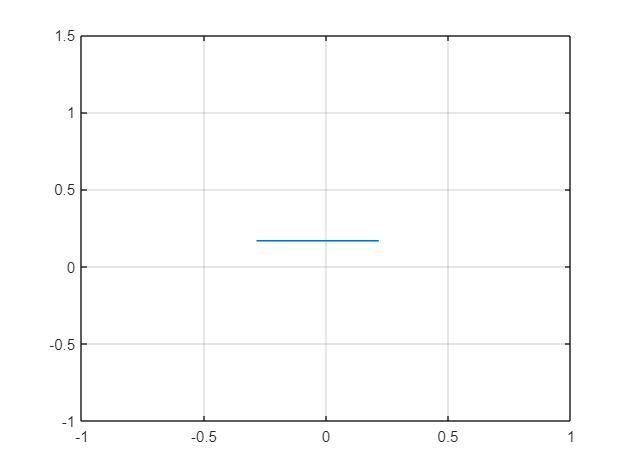

x_ker=-pi/4+0.5:0.1:pi/4-0.5; % create x range for kernel
ker=ones(size(x_ker)); % create the kernel train
ker=ker/sum(ker); % normalize the kernel values

figure;
plot(x_ker,ker);
xlim([-1 1]);
grid on

Last, the convolution was conducted:

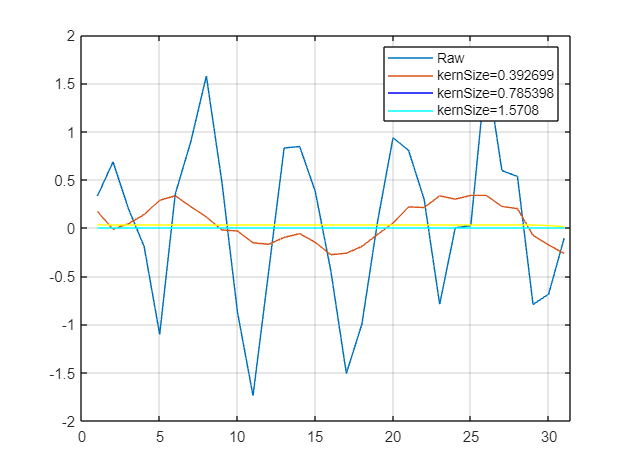

fconv=conv(f,ker,'same'); % conduct convolution

figure;
plot(x,[f', fconv']);
xlim([0 10*pi]);
grid on
legend('original signal','convoluted signal');
kernSize=[pi/8 pi/4 pi/2]; % setup the kernel size of convolution
nk=length(kernSize);
clr=jet(nk);

for ik=1:nk
    kernSize1=kernSize(ik); % grab out ik-th kernel size
    x1=-kernSize1/2+0.5:0.01:kernSize1/2-0.5; % setup the window range
    g=ones(size(x1)); % setup the kernel for convolution
    g=g/sum(g); % normalize the kernel

    fconv=conv(f,g,'same'); % convolution
    line(x,fconv,color=clr(ik,:));
end
legend(cat(2,{'Raw'},compose('kernSize=%g',kernSize)));

From the above plotting results, it does shows that the convolution kernel does act like a low pass filter for reducing noise. The low-pass filter usually have a -45 degree shift from the original signal. From the smallest size kernel size, the angle shift can be seen compared to the original signal. As the increment of the kernel size, the magnitude of the convoluted signal becomes smaller and smaller. Therefore, the relationship between the kernel size and the magnitude of the convoluted signal is opposite.

**Problem 1.5:**

For this problem, the equation:

**delta_x_ker = (z_samp) / (z_img) * (delta_x_img) + (diameter of lens) * ((z_samp) / (z_focal plane) - 1)**

needs to be derived. 

To start with this, the symbolic computation is setup.

% setup symbolic computation
syms f z_samp z_fp z_img x_img D positive
syms theta_img z

assume(z_samp > z_fp);

rIn=[x_img theta_img]'; % setup input light ray (In this case, the input light ray comes from the sensor)

Then, we setup the RTM for camera inner environment, lens, and air environement:

RTM_air_sam=[1 z-z_fp;0 1]; % setup RTM for air between z sample and focal plane
RTM_air_FP=[1 z_fp;0 1]; % setup RTM for air between focal plane and lens
RTM_lens=[1 0;-1/f 1]; % setup RTM for lens
RTM_inn=[1 z_img;0 1]; % setup RTM for inner environment
RTM_sys=RTM_air_sam*RTM_air_FP*RTM_lens*RTM_inn; % setup RTM for the entire environment

Later, we setup the output function:

rOut=RTM_sys*rIn; % output ray function (In this case, the sample part is the output part)
xOut(z,theta_img,f,z_samp,z_fp, z_img,x_img)=-rOut(1); % set the first element of the rOUt function as xOut
theta_img1=((D-x_img)/2)/z_img; % setup angle for input light ray for upper image light ray
theta_img2=-((D-x_img)/2)/z_img; % setup angle for input light ray for lower image light ray
x_img1 = x_img/2;
x_img2 = -x_img/2;

xOut1 = xOut(z_samp,theta_img1,f,z_samp,z_fp,z_img,x_img1);
xOut2 = xOut(z_samp,theta_img2,f,z_samp,z_fp,z_img,x_img2);
x_diff = xOut1-xOut2

$$x\_diff = x_{\mathrm{img}}\,\left(\frac{z_{\mathrm{samp}}}{f}-1\right)-\frac{2\,\left(z_{\mathrm{samp}}-z_{\mathrm{img}}\,\left(\frac{z_{\mathrm{samp}}}{f}-1\right)\right)\,\left(\frac{\text{D}}{2}-\frac{x_{\mathrm{img}}}{2}\right)}{z_{\mathrm{img}}}$$

For paraxial ray, we can make the assumption that:

**atan(theta) = theta**

And for z_focal plan, we have:

**z_fp = 1 / (1/f - 1/z_img) = z_img - f / z_img*f**

**We can subsititue the notation from the x_diff outcome. The outcome from the x_diff found to match the equation 1.9.**

For the second portion of the problem, RTM analysis is utilized to prove the derivation of equation:

**delta_z_DOF = ((m+1)*delta_x_img) / (m^2 * NA - ((m+1)^2) / (4*NA) * (delta_x_img / z_img)^2**

Once again, we use the symbolic computation we set up in the previous section:

x_cen=0;
theta_cen=(D/2)/z_img;
x_corn=x_img/2;
theta_corn=-(x_img/2)/z_img;
x_diff(z,f,z_samp,z_fp,z_img) = abs(xOut(z,theta_cen,f,z_samp,z_fp,z_img,x_cen) ...
                                    - xOut(z,theta_corn,f,z_samp,z_fp,z_img,x_corn)); 
ans1=solve(x_diff==0,z)

$$ans1 = -\frac{\text{D}\,f\,z_{\mathrm{img}}}{\text{D}\,f-\text{D}\,z_{\mathrm{img}}+f\,x_{\mathrm{img}}}$$

x_cen2=0;
theta_cen2=-(D/2)/z_img;
x_corn2=x_img/2;
theta_corn2=-(x_img/2)/z_img;
x_diff(z,f,z_samp,z_fp,z_img) = abs(xOut(z,theta_cen2,f,z_samp,z_fp,z_img,x_cen2) ...
                                    - xOut(z,theta_corn2,f,z_samp,z_fp,z_img,x_corn2));
ans2=solve(x_diff==0,z)

$$ans2 = \frac{\text{D}\,f\,z_{\mathrm{img}}}{\text{D}\,z_{\mathrm{img}}-\text{D}\,f+f\,x_{\mathrm{img}}}$$

DOF=ans1-ans2

$$DOF = -\frac{\text{D}\,f\,z_{\mathrm{img}}}{\text{D}\,f-\text{D}\,z_{\mathrm{img}}+f\,x_{\mathrm{img}}}-\frac{\text{D}\,f\,z_{\mathrm{img}}}{\text{D}\,z_{\mathrm{img}}-\text{D}\,f+f\,x_{\mathrm{img}}}$$

**Problem 1.6**

For this question, the depth of random noise effect will be observed.

To begin with this problem, we first implement the camera set we have from example 1.5, and calculate the z positions for the sample and noise layer:

clear

nx=100; ny=80; % define the pixel number (100*80 pixels)
dxSamp=5; % define the sampling rate (5um)
dxImg=10;
dxp=0.1; % define the pixel size (0.1um)
zImg=300e3;  % the lens-sensor distance [um]
f=100e3;  % the focal length [um]
diaAper=50e3;  % the aperture diameter [um]

% determine focal plane position
zFP=1/(1/f-1/zImg)  % the focal plane position [um] (Eq. 1.7)

zFP = 1.5000e+05

dxFP=zFP/zImg*dxImg  % the sampling interval on the focal plane [um] (Eq. 1.8)

dxFP = 5.0000

zSamp=zFP;
dxSamp=dxFP;
zNoise = zFP + 1;  % the sample position [um]
dxNoise = zNoise/zImg*dxImg  % the sampling interval on the sample plane [um] (Eq. 1.4)

dxNoise = 5.0000

Next, the image and noise files are loaded:

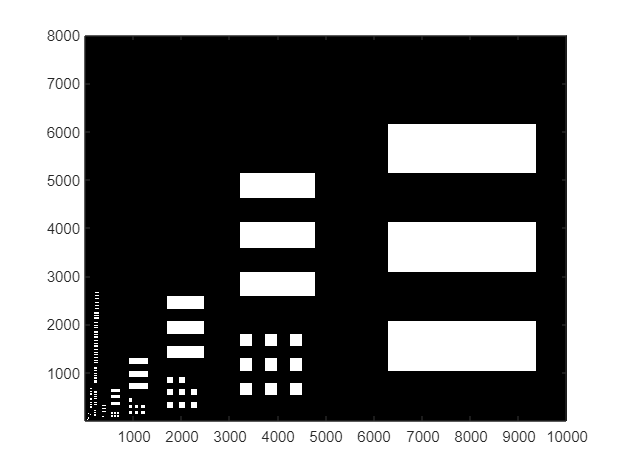

% load image file
load("virtualTarget.mat","phySamp");
phySamp=double(phySamp);
[nxp,nyp]=size(phySamp);

% load noise file
load("virtualNoise.mat","phyNoise");
phyNoise=double(phyNoise);
[noise_nxp,noise_nyp]=size(phyNoise);

% show out the picture 
figure;
imagesc(phySamp')
ax=gca;
ax.Colormap=gray;
ax.YDir='normal';
ax.DataAspectRatio=[1 1 1];

Next, we conduct the convolution for the sample image first:

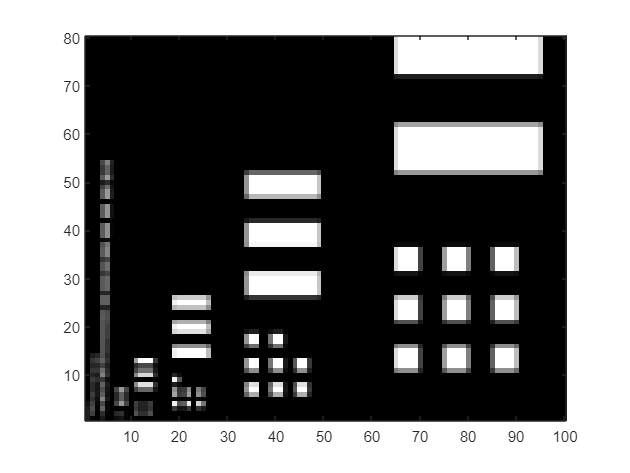

dxKernPhy=round(dxSamp/dxp);
kern=ones(dxKernPhy,dxKernPhy);
kern=kern/sum(kern(:));
SampConv=convn(phySamp,kern,'same');
dxSamPhy=round(dxSamp/dxp);
SampConv2=SampConv(round(dxSamPhy/2):dxSamPhy:end, round(dxSamPhy/2):dxSamPhy:end);
if size(SampConv2,1)>nx
    SampConv2=SampConv2(1:nx,:);
end
if size(SampConv2,2)>ny
    SampConv2=SampConv2(:,1:ny);
end
figure
imagesc(SampConv2')
ax=gca;
ax.Colormap=gray;
ax.YDir='normal';
ax.DataAspectRatio=[1 1 1];

After the convolution for sample image, the convolution of the noise layer is then conducted:

dxKernNoi = zNoise/zImg*dxImg + diaAper*abs(zNoise/zFP-1)  % kernel size [um]kern=ones(dxKernPhy,dxKernPhy);

dxKernNoi = 5.3334

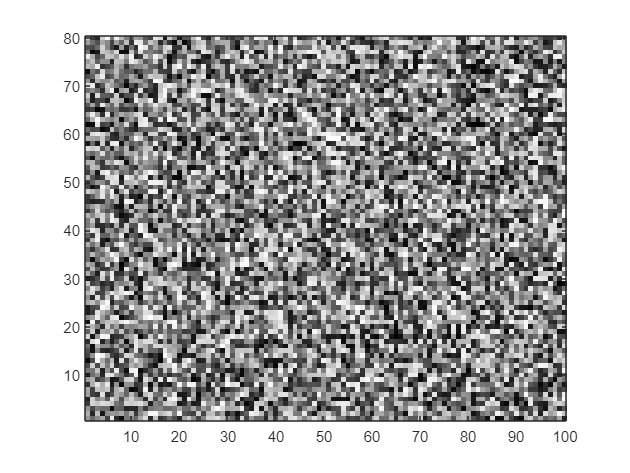

dxKernNoi = round(dxKernNoi/dxp);  % the kernel size in terms of physical pixel number
kernNoi = ones(dxKernNoi,dxKernNoi);
kernNoi=kernNoi/sum(kernNoi(:));
NoiConv=convn(phyNoise,kernNoi,'same');
dxSamNoi=round(dxNoise/dxp);
NoiConv2=NoiConv(round(dxSamNoi/2):dxSamNoi:end, round(dxSamNoi/2):dxSamNoi:end);
if size(NoiConv2,1)>nx
    NoiConv2=NoiConv2(1:nx,:);
end
if size(NoiConv2,2)>ny
    NoiConv2=NoiConv2(:,1:ny);
end
figure
imagesc(NoiConv2')
ax=gca;
ax.Colormap=gray;
ax.YDir='normal';
ax.DataAspectRatio=[1 1 1];

In the last, the outcomes from two convolutions are added together:

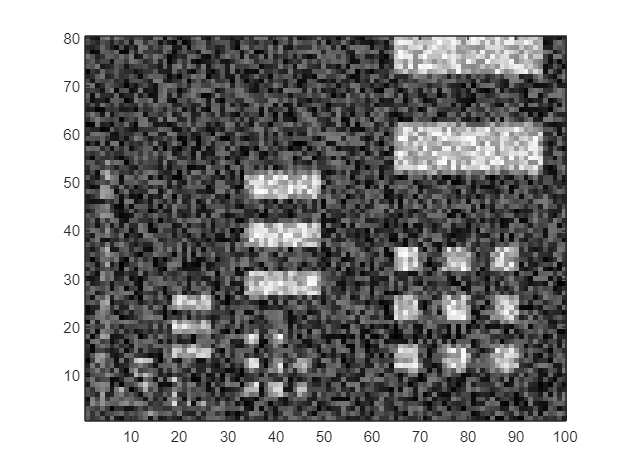

Outcome=SampConv2+NoiConv2;
figure
imagesc(Outcome')
ax=gca;
ax.Colormap=gray;
ax.YDir='normal';
ax.DataAspectRatio=[1 1 1];

disp(['Difference = ' num2str(mean((SampConv2(:)-Outcome(:)).^2),3)]);

Difference = 0.319


From the outcome shown above, the result does show noisier than the original convolution outcome.

By observing different depth of noise effect, the depth of the noise is then be changed to 10 um away from the focal plane.

zNoise = zFP + 10;  % the noise position [um]
dxKernNoi = zNoise/zImg*dxImg + diaAper*abs(zNoise/zFP-1)  % kernel size [um]kern=ones(dxKernPhy,dxKernPhy);

dxKernNoi = 8.3337

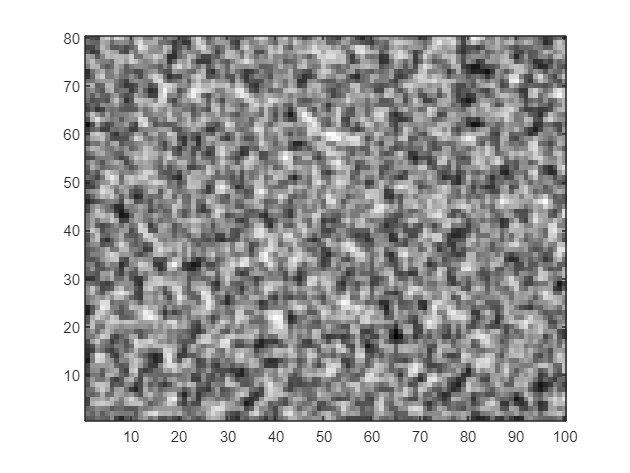

dxKernNoi = round(dxKernNoi/dxp);  % the kernel size in terms of physical pixel number
kernNoi = ones(dxKernNoi,dxKernNoi);
kernNoi=kernNoi/sum(kernNoi(:));
NoiConv=convn(phyNoise,kernNoi,'same');
dxSamNoi=round(dxNoise/dxp);
NoiConv2=NoiConv(round(dxSamNoi/2):dxSamNoi:end, round(dxSamNoi/2):dxSamNoi:end);
if size(NoiConv2,1)>nx
    NoiConv2=NoiConv2(1:nx,:);
end
if size(NoiConv2,2)>ny
    NoiConv2=NoiConv2(:,1:ny);
end
figure
imagesc(NoiConv2')
ax=gca;
ax.Colormap=gray;
ax.YDir='normal';
ax.DataAspectRatio=[1 1 1];

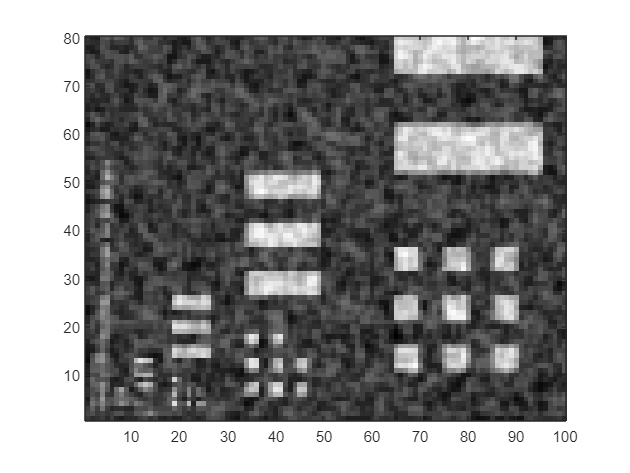

Outcome=SampConv2+NoiConv2;
figure
imagesc(Outcome')
ax=gca;
ax.Colormap=gray;
ax.YDir='normal';
ax.DataAspectRatio=[1 1 1];

disp(['Difference = ' num2str(mean((SampConv2(:)-Outcome(:)).^2),3)]);

Difference = 0.267


In the case of 10um, the noise effect is more slightly compared to the case of 1um. This can be viewed in the difference from the two settings.

In the concept of depth of field, the closer the object is to the focal plane, the more concentrated it will be on the sensor plane (image plane). Therefore, from the above example, it can be seen that the 1um case is more noisy compared to 10um case since the noise object is more concentrated in 1um case. As a result of overlapping, the outcome image is more noisy.